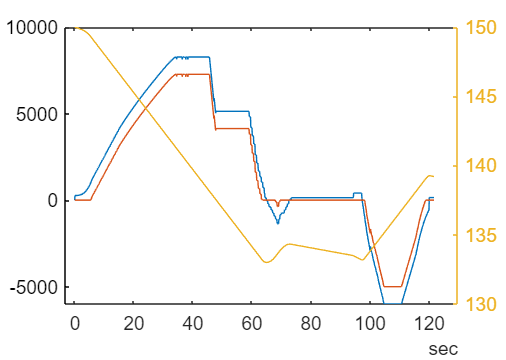

% Berechnung CR:

Leistung = 1000;
Energie = 150;
SimStreckenU.ZH_HBFahrtzeit120.EBat(:) = Energie;
CR = 0.1;
while min(SimStreckenU.ZH_HBFahrtzeit120.EBat) > 0

    CR = CR + 0.005;
    SimStreckenU.ZH_HBFahrtzeit120.EBat(:) = Energie;
    SimStreckenU.ZH_HBFahrtzeit120.LeistungBat(:) = 0;

    for k = 2:height(SimStreckenU.ZH_HBFahrtzeit120)
        if (SimStreckenU.ZH_HBFahrtzeit120.Leistung(k) >= 0 && SimStreckenU.ZH_HBFahrtzeit120.Leistung(k) * CR <= Leistung)
            SimStreckenU.ZH_HBFahrtzeit120.LeistungBat(k) = SimStreckenU.ZH_HBFahrtzeit120.Leistung(k) - SimStreckenU.ZH_HBFahrtzeit120.Leistung(k) * CR;
            SimStreckenU.ZH_HBFahrtzeit120.EBat(k) = SimStreckenU.ZH_HBFahrtzeit120.EBat(k-1) - SimStreckenU.ZH_HBFahrtzeit120.Leistung(k) * CR * const.dt/3600;

        elseif (SimStreckenU.ZH_HBFahrtzeit120.Leistung(k) >= 0 && SimStreckenU.ZH_HBFahrtzeit120.Leistung(k) * CR > Leistung)
            SimStreckenU.ZH_HBFahrtzeit120.LeistungBat(k) = SimStreckenU.ZH_HBFahrtzeit120.Leistung(k) - Leistung;
            SimStreckenU.ZH_HBFahrtzeit120.EBat(k) = SimStreckenU.ZH_HBFahrtzeit120.EBat(k-1) - Leistung * const.dt/3600;

        elseif (SimStreckenU.ZH_HBFahrtzeit120.Leistung(k) < 0 && abs(SimStreckenU.ZH_HBFahrtzeit120.Leistung(k)) * CR <= Leistung)
            SimStreckenU.ZH_HBFahrtzeit120.LeistungBat(k) = SimStreckenU.ZH_HBFahrtzeit120.Leistung(k) + abs(SimStreckenU.ZH_HBFahrtzeit120.Leistung(k)) * CR;
            SimStreckenU.ZH_HBFahrtzeit120.EBat(k) = SimStreckenU.ZH_HBFahrtzeit120.EBat(k-1) - SimStreckenU.ZH_HBFahrtzeit120.Leistung(k) * CR * const.dt/3600;

        elseif (SimStreckenU.ZH_HBFahrtzeit120.Leistung(k) < 0 && abs(SimStreckenU.ZH_HBFahrtzeit120.Leistung(k)) * CR > Leistung)
            SimStreckenU.ZH_HBFahrtzeit120.LeistungBat(k) = SimStreckenU.ZH_HBFahrtzeit120.Leistung(k) + Leistung;
            SimStreckenU.ZH_HBFahrtzeit120.EBat(k) = SimStreckenU.ZH_HBFahrtzeit120.EBat(k-1) + Leistung * const.dt/3600;
        end
    end
    if (CR >= 1)
        break
    end
end
cla reset
plot(SimStreckenU.ZH_HBFahrtzeit120.time, SimStreckenU.ZH_HBFahrtzeit120.Leistung)
hold on
plot(SimStreckenU.ZH_HBFahrtzeit120.time, SimStreckenU.ZH_HBFahrtzeit120.LeistungBat)
yyaxis right
plot(SimStreckenU.ZH_HBFahrtzeit120.time, SimStreckenU.ZH_HBFahrtzeit120.EBat)